# Adams-Verfahren und Prädiktor-Korrektor-Verfahren

Wir betrachten folgendes einfache Anfangswertproblem, mit einem Parameter $\lambda <0$: 

    $y'(t)= \lambda y(t)-\lambda \sin(t) + \cos(t), ~~t \in [0,2],~~y(0)=1$ .

Die  Lösung  dieses Problems ist $y(t)=e^{\lambda t} +\sin(t)$. 

Zur numerischen Approximation der Lösung werden folgende Verfahren verwendet (siehe Buch):

-   das explizite Adams-Bashforth $3$-Schritt-Verfahren,

-   das implizite Adams-Moulton $3$-Schritt-Verfahren,

-   das explizite ABM3 Prädiktor-Korrektor-Verfahren.

 (Auswählbar mit dem Parameter `choice`):

Wir verwenden eine  Schrittweite  $h=2^{-k}$, $k=4,\ldots,8.$  Der Einfachheit halber nehmen wir für die Startwerte $y^j$, $j=0,1,2$, die exakte Lösung $y^j:=y(t_j)$, $j=0,1,2$.  Der Fehler am Endzeitpunkt, $|y^n-y(2)|$, wird gezeigt. Außerdem wird der Fehlerreduktionsfaktor bei Halbierung der Schrittweite angegeben.

# Aktivität:

Sie können die Methode wählen und den Parameter $\lambda \in [-100,-1]$ variieren.

Enspricht die beobachtete Fehlerreduktion der Konvergenzordnung der Methode? Was passiert bei größeren $|\lambda|$-Werten?

lambda=-20

lambda = -20

choice=2;
method= {'Adams-Bashfort', 'Adams-Moulton', 'Praediktor-Korrektor'};
T=2;
ystart=1;
lsg= @(t) exp(lambda*t) + sin(t); % exakte Loesung als Funktion von t
yexakt=lsg(T);
error=zeros(5,1);  hh= error;
fprintf('Methode: %s\n------------------------------\n', method{choice});

Methode: Adams-Moulton
------------------------------


fprintf('\nFehler am Endzeitpunkt für h=1/16,...., 1/256 und Fehlerreduktionsfaktor:\n');


Fehler am Endzeitpunkt für h=1/16,...., 1/256 und Fehlerreduktionsfaktor:


for k=4:8
    h=2^(-k); n=2*2^k;
    yalt3= lsg(0);  yalt2= lsg(h);  yalt1= lsg(2*h);
    for j=2:n-1   % Bestimmung der Annaeherung y^(j+1)
        switch choice
            case 1  % Adams-Bashforth
                yneu= AB( lambda, h, j, yalt1, yalt2, yalt3);
            case 2  % Adams-Moulton
                yneu= AM( lambda, h, j, yalt1, yalt2, yalt3);
            case 3  % Praediktor-Korrektor
                yneu= PC( lambda, h, j, yalt1, yalt2, yalt3);
        end
        yalt3=yalt2; yalt2=yalt1; yalt1=yneu; % Variablenshift
    end
    disp('-----------------'); 
    format shorte; Fehler= abs(yneu-yexakt)
    kk= k-3; % index starting with 1
    hh(kk)= h;  error(kk)= Fehler;
    if (kk>1) 
        format short; Fehlerreduktionsfaktor= error(kk-1)/error(kk) 
    end
end

-----------------


Fehler = 6.5096e-09

-----------------


Fehler = 4.3631e-10

Fehlerreduktionsfaktor = 14.9197

-----------------


Fehler = 2.8177e-11

Fehlerreduktionsfaktor = 15.4845

-----------------


Fehler = 1.7893e-12

Fehlerreduktionsfaktor = 15.7471

-----------------


Fehler = 1.1258e-13

Fehlerreduktionsfaktor = 15.8945

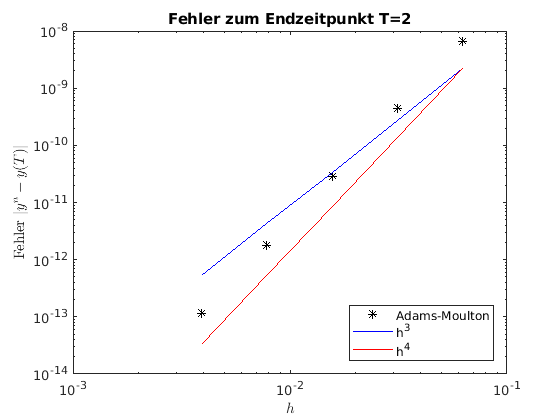

plotError( hh, error, T, method{choice});

function y= AB(lambda,h,j,yalt1,yalt2,yalt3)  % Adams-Bashfort 3-Schritt-Verfahren
    tj= j*h;
    y= yalt1 + h/12*(23*f(lambda,tj,yalt1) - 16*f(lambda,tj-h,yalt2) + 5*f(lambda,tj-2*h,yalt3));
end

function y= AM(lambda,h,j,yalt1,yalt2,yalt3)  % Adams-Moulton 3-Schritt-Verfahren; kann man explizit umformulieren 
    tj= j*h;
    yzwischen= yalt1 + h/24*(9*(-lambda*sin(tj+h) + cos(tj+h)) + 19*f(lambda,tj,yalt1) - 5*f(lambda,tj-h,yalt2) + f(lambda,tj-2*h,yalt3));
    y= yzwischen / (1 - 9/24*h*lambda);
end
 

function y= PC(lambda,h,j,yalt1,yalt2,yalt3)  % Praediktor-Korrektor-Verfahren ABM3
    tj= j*h;
    % Praediktor-Schritt
    yzwischen= yalt1 + h/12*(23*f(lambda,tj,yalt1) - 16*f(lambda,tj-h,yalt2) + 5*f(lambda,tj-2*h,yalt3));
    % Korrektor-Schritt
    y= yalt1 + h/24*(9*f(lambda,tj+h,yzwischen) + 19*f(lambda,tj,yalt1) - 5*f(lambda,tj-h,yalt2) + f(lambda,tj-2*h,yalt3));
end

function fout= f(lambda,t,y)   % rechte Seite der DGLn
    fout= lambda*y - lambda*sin(t)+cos(t);
end

function plotError( h, error, T, method) 
% Fehlerplot
clf
loglog(h,error,'k*');
hold on;
scale= error(1)/3;
hs= h(1);
loglog(h,scale*(h/hs).^3,'b-', h,scale*(h/hs).^4,'r-');
title( ['Fehler zum Endzeitpunkt T=',num2str(T)]);
legend(method, 'h^3', 'h^4', 'Location','southeast');
xlabel('$h$','Interpreter','latex'); ylabel('Fehler $|y^n-y(T)|$','Interpreter','latex');
hold off;
end